**SimpleUSBCameraTutorial.mlx is a template for future Fun-Robo USB camera code**

This is a simple color object tracking USB Camera Tutorial for your robots.

*This example shows how to use the snapshot function to acquire live images from USB webcams. To use it you need to first load:*

***MATLAB® Support Package for USB Webcams ****which provides the ability to bring *

*live images from any USB video class (UVC) compliant webcam into MATLAB.*

*Available USB webcam functions:*

- *webcamlist	- List of webcams connected to your system*

- *webcam	        - Connection to a webcam*

- *preview	        - Preview live video data from webcam*

- *snapshot	        - Acquire single image frame from a webcam*

- *closePreview	- Close webcam preview window*

Sign* your names here* and give *the creation date* and* revision number*

clc                     % clear command window
clear                   % clear MATLAB workspace
imaqreset               % clear all image objects from memory

**Set up robot control system** ( code that runs once )

% Identifying Available Webcams,The webcamlist function provides a cell array
% of all webcams on the current system that MATLAB can access.
% webcam(2) is hopefully {'Microsoft LifeCam Cinema'}, if not cahnge code
% below

camList = webcamlist  

camList = 2×1 cell array
    {'Integrated Webcam'}
    {'HD Web Camera'    }


% Set up Connection to the LifeCam Webcam, print its properties
robotCam = webcam(2)

robotCam =   webcam with properties:

                     Name: 'HD Web Camera'
     AvailableResolutions: {'1920x1080'  '1280x960'  '1280x720'  '800x600'  '640x480'  '640x360'}
               Resolution: '1920x1080'
               Saturation: 128
                 Contrast: 128
             WhiteBalance: 417
               Brightness: 100
         WhiteBalanceMode: 'auto'
    BacklightCompensation: 0
                      Hue: 128
                Sharpness: 128


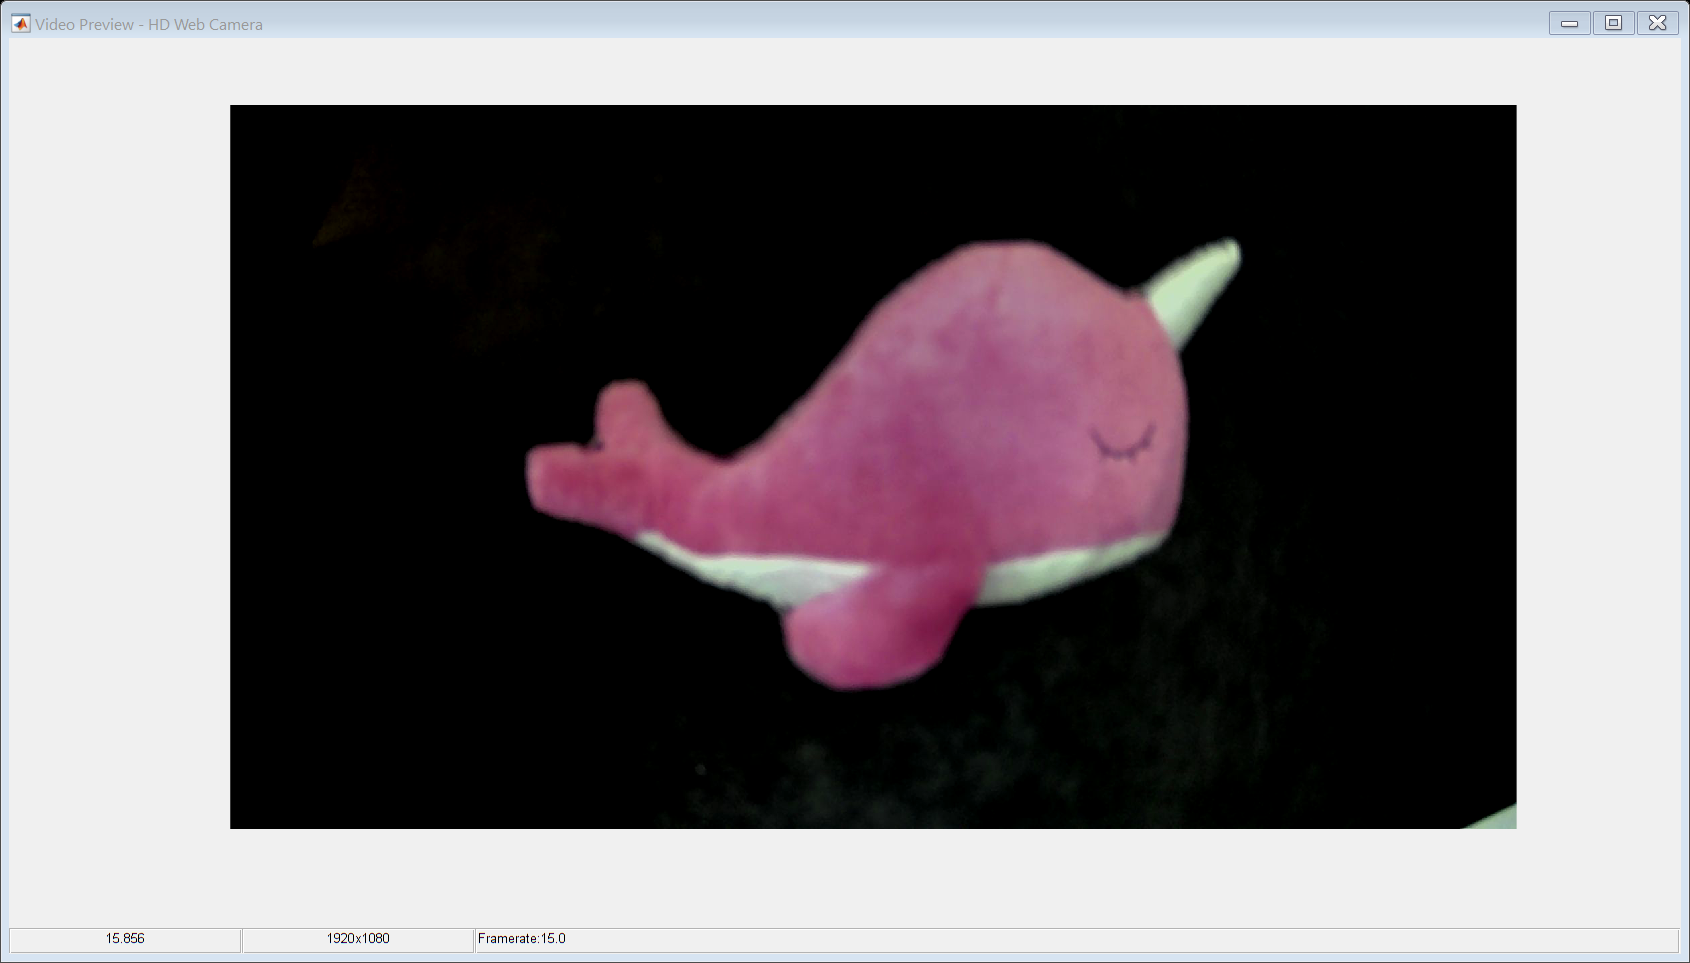

% Fix auto exposure problem set it to manual, set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorythms crazy by constantly changing
SETUPUSBCAMERA(robotCam);

% Preview Video Stream
preview(robotCam)
% wave hand about to make sure camera is working
gcamtest= input('move hand in front of camera, type G, then hit ENTER ','s');

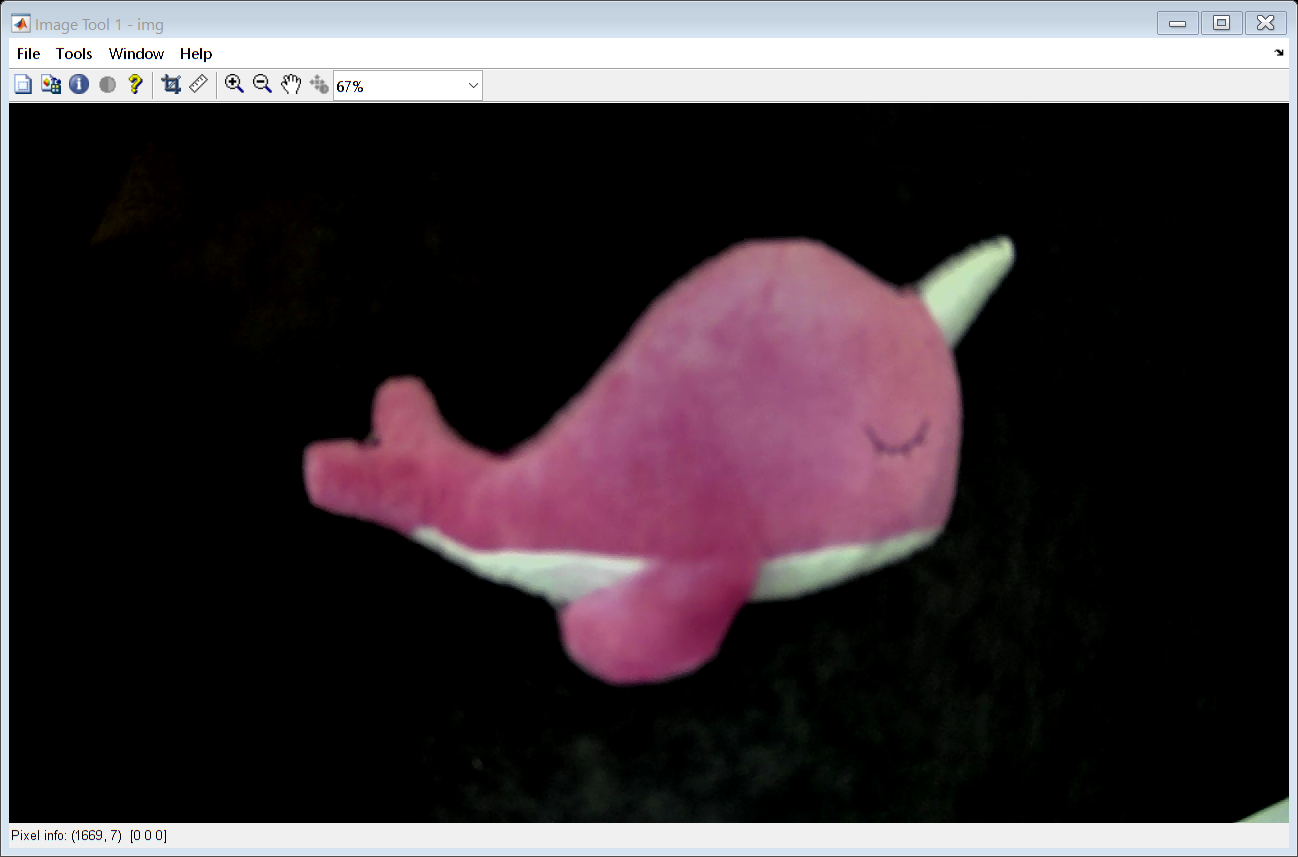

clc;

% close Preview window
closePreview(robotCam);

% Acquire a Frame
img = snapshot(robotCam);

% Display the frame in a figure window.
% imaqtool launches an interactive GUI to allow you to explore, configure, 
% and acquire data from your installed and supported image acquisition devices.
imtool(img);

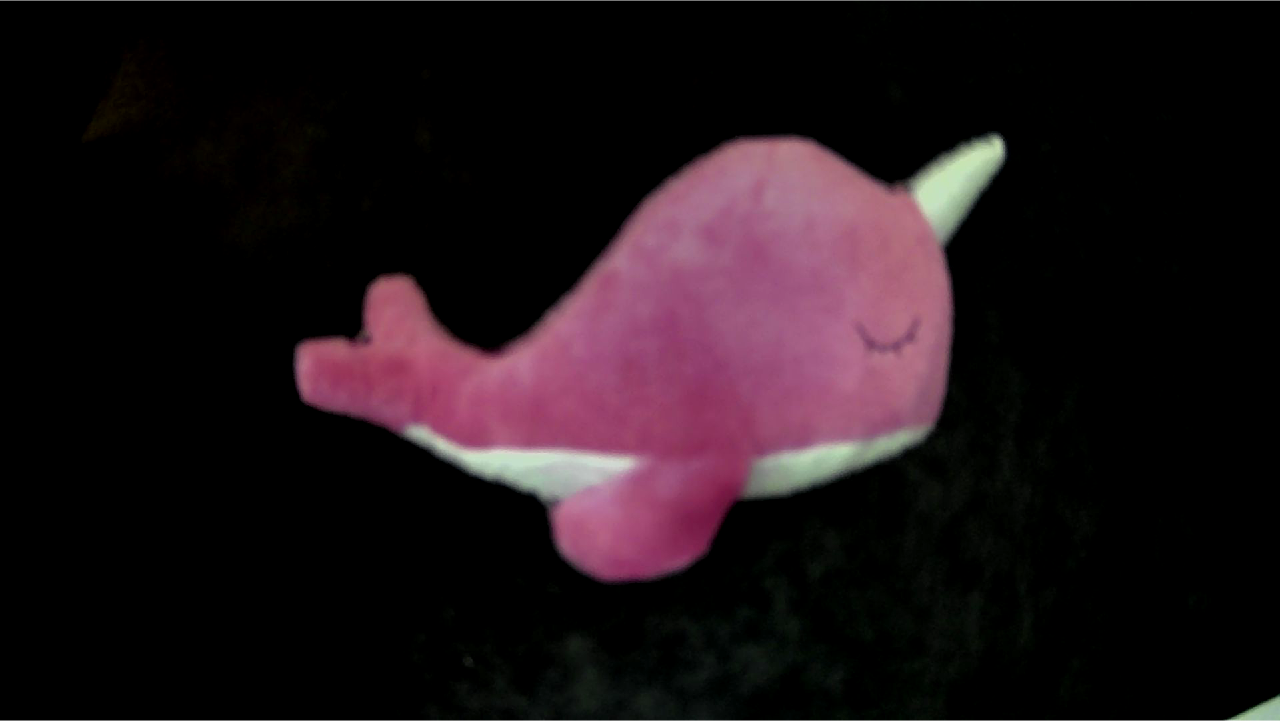


% explore image with tool
gcamtest= input('experiment with tool, type G, then hit ENTER ','s');
clc;

% livescript does some funky stuff when you try to update in line images quickly, so
% create a free floating figure for images to deal with livescript update problem
camWindow= figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
figure(camWindow)                              % go to camWindow for imshow           
imshow(img,'Border','tight')


% Configure test loop to collect n data points.  
  
nTests = input(['Enter small number of camera tests, ' ...
    'followed by enter: ']);
clc                     % clear command window

% preallocate image array memory

%robotImg = zeros(1080, 1920, nTests, 'unit8')  

Error using zeros
CLASSNAME input must be a valid numeric or logical class name.



  
r = rateControl(0.1);        % create a 0.1 hz loop rate 
reset(r);                    % reset loop time to zero  

**Run robot control loop **( code that runs over and over )

controlFlag = 1;                 % create a loop control
while (controlFlag < nTests+1)   % loop till ntests data captured
    
    robotIMG(controlFlag) = SENSE(robotCam);   % capture a USB camera image
    
    figure(camWindow)                          % go to camWindow to show new image with imshow           
    %imshow(robotIMG,'Border','tight')          % show image in camWindow figure
    image(robotIMG)                             % show image in camWindow figure
    
    THINK();                     % compute what robot should do next
    ACT();                       % command robot actuators
    
    % store experimental commanded versus actual data
    camtest= input('move object to new position, type G, then hit ENTER ','s');
    clc;
 
    waitfor(r);                  % wait for loop cycle to complete 
    controlFlag = controlFlag+1; % increment loop
end  

### Mission data processing

For many robot applications, you will need to post-process the data collected after

the mission. Here we will plot the measured versus actual range positions.

% Add post processing code here, mmight be good to downoad images to a
% MATLAB drive location where you can work on processing them latter
  

### Clean shut down

finally, with most embeded robot controllers, its good practice to put 

all actualtors into a safe position and then release all control objects and shut down all

communication paths. This keeps systems form jamming when you want to run again.

% Stop program and clean up the connection to WebCam
% when no longer needed 
  
  clc
  clear robotCam           % connection is no longer needed, clear the cam variable.
  disp('SimpleUSBCameraTutorial Done');
  beep        % play system sound to let user know program is ended 

**Robot Functions **(store this codes local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions

  % No general robot functions in this script

**Sense Functions** (store all Sense related local functions here)

function []= SETUPUSBCAMERA(robotCam)
    % SETUPUSBCAMERA creates and configures an Webcam to be a simple robot 
    % vision system. It requires a standard Webcam attached to 
    % your computer and takes webcam object name as sole input
    % You need to set your cameras unique parameters to optimize picture
    % D. Barrett 2021 Rev A

    % Fix auto exposure set it to manual, set whitebalance to manual too
    %robotCam.ExposureMode = 'manual';   for LifeCam
    robotCam.WhiteBalanceMode = "manual";
    % experimentally determing best exposure setting for lab, enter here
    %robotCam.Exposure = -8 ;      % for LifeCam
    %robotCam.WhiteBalanceMode = 'manual' ;  % for LifeCam
    robotCam.Brightness = 100;
end

function [robotImage] = SENSE(robotCam)
    % This function aquires a single image from the USBCamera testCam
    % and displays it in a stand alone figure
    % D. Barrett 2021 Rev A

   robotImage = snapshot(robotCam);
   % Show acquired image
   imshow(robotImage);
   
end

**Think Functions** (store all Think related local functions here)

function THINK()
   % null function, not much thinking to do here.
end

**Act Functions** (store all Act related local functions here)

function ACT()
% null function, not much acting to do here.
end